close all;
clear;
clc;


## Question 1

## part a-b

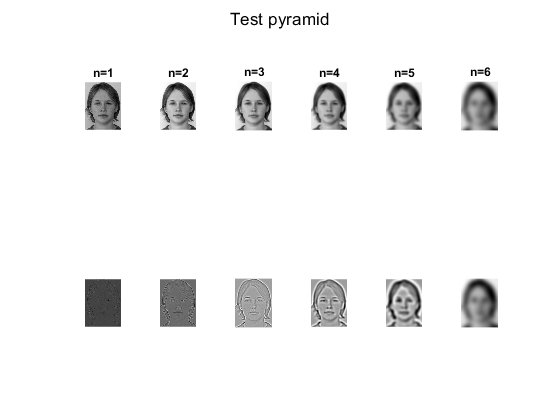


image = imread("data\Inputs\imgs\0004_6.png");
image_gray = im2double(rgb2gray(image));
n = 6;
[G, L] = pyrGen(image_gray, n);

figure();
sgtitle('Test pyramid');
for i=1:n
    subplot(2,6,i);
    imshow(G{i}, []);
    title(['n=', num2str(i)]);
    
    subplot(2,6,6 + i);
    imshow(L{i}, []);
end

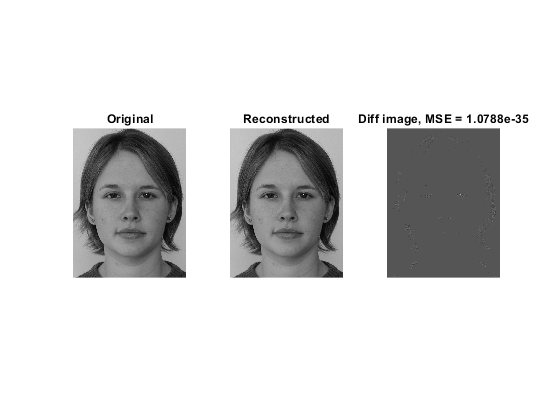


recon_image = imRecon(L);

sub_image = image_gray - recon_image;

mse = immse(image_gray, recon_image);

figure();
subplot(1,3,1);
imshow(image_gray, []);
title('Original');

subplot(1,3,2);
imshow(recon_image, []);
title('Reconstructed');

subplot(1,3,3);
imshow(sub_image, []);
title(['Diff image, MSE = ', num2str(mse)]);

## part c - f

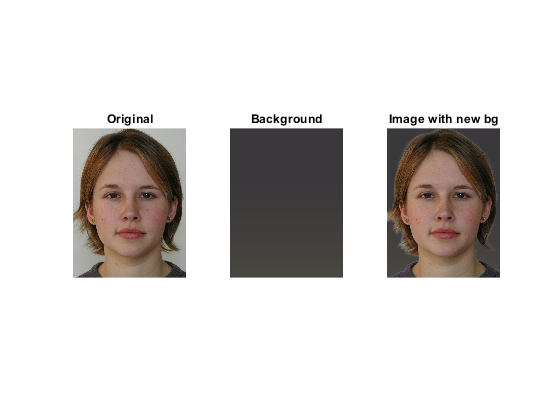

I = im2double(imread("data\Inputs\imgs\0004_6.png"));
E_16 = im2double(imread("data\Examples\imgs\6.png"));
mask = im2double(imread("data\Inputs\masks\0004_6.png"));
bg_16 = im2double(imread("data\Examples\bgs\6.jpg"));
n = 6;
styledI_16 = styleTransfer(I,E_16,mask,bg_16, n);

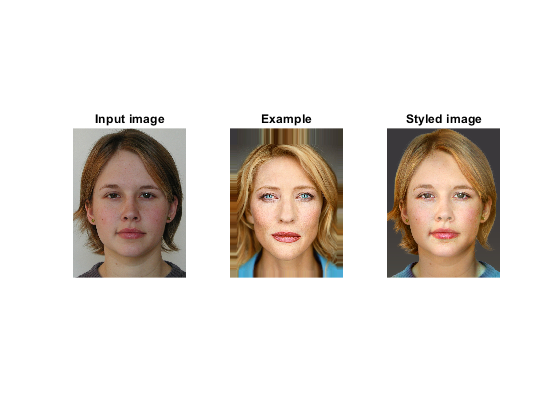


figure();
subplot(1,3,1);
imshow(I, []);
title('Input image');
subplot(1,3,2);
imshow(E_16, []);
title('Example')
subplot(1,3,3);
imshow(styledI_16);
title('Styled image');

## part g

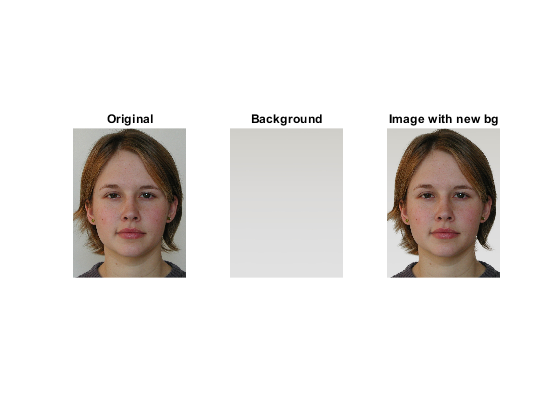

I = im2double(imread("data\Inputs\imgs\0004_6.png"));
mask = im2double(imread("data\Inputs\masks\0004_6.png"));
E_16 = im2double(imread("data\Examples\imgs\16.png"));
bg_16 = im2double(imread("data\Examples\bgs\16.jpg"));
E_21 = im2double(imread("data\Examples\imgs\21.png"));
bg_21 = im2double(imread("data\Examples\bgs\21.jpg"));
n = 6;
styledI_21 = styleTransfer(I,E_21,mask,bg_21, n);

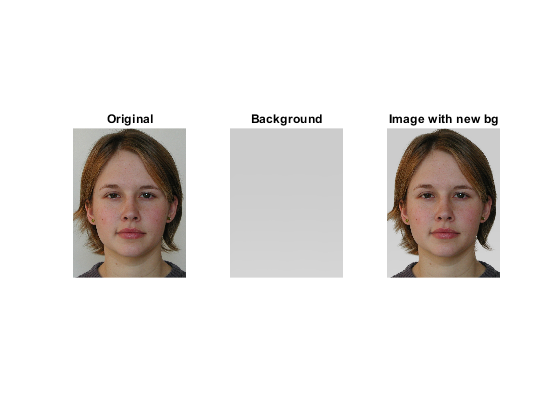

styledI_16 = styleTransfer(I,E_16,mask,bg_16, n);

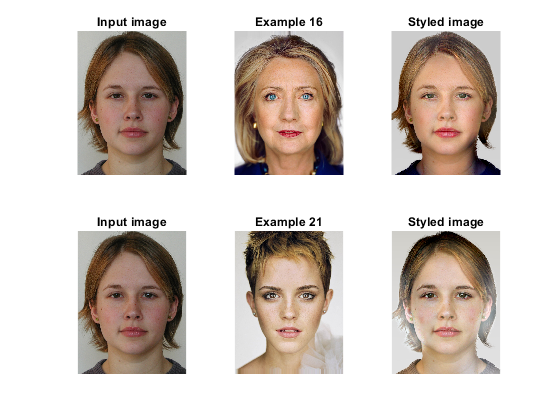


figure();
subplot(2,3,1);
imshow(I, []);
title('Input image');
subplot(2,3,2);
imshow(E_16, []);
title('Example 16')
subplot(2,3,3);
imshow(styledI_16);
title('Styled image');

subplot(2,3,4);
imshow(I, []);
title('Input image');
subplot(2,3,5);
imshow(E_21, []);
title('Example 21')
subplot(2,3,6);
imshow(styledI_21);
title('Styled image');

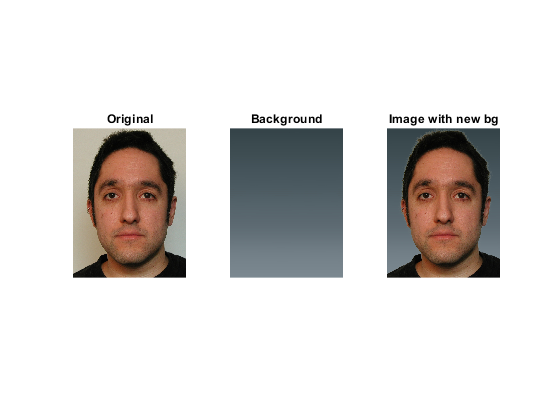



I = im2double(imread("data\Inputs\imgs\0006_001.png"));
mask = im2double(imread("data\Inputs\masks\0006_001.png"));
E_0 = im2double(imread("data\Examples\imgs\0.png"));
bg_0 = im2double(imread("data\Examples\bgs\0.jpg"));
E_9 = im2double(imread("data\Examples\imgs\9.png"));
bg_9 = im2double(imread("data\Examples\bgs\9.jpg"));
E_10 = im2double(imread("data\Examples\imgs\10.png"));
bg_10 = im2double(imread("data\Examples\bgs\10.jpg"));

styledI_0 = styleTransfer(I,E_0,mask,bg_0, n);

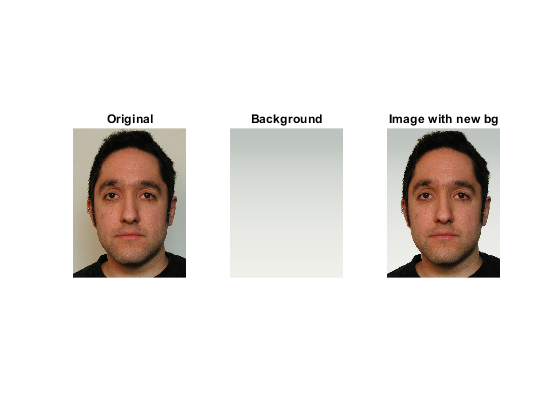

styledI_9 = styleTransfer(I,E_9,mask,bg_9, n);

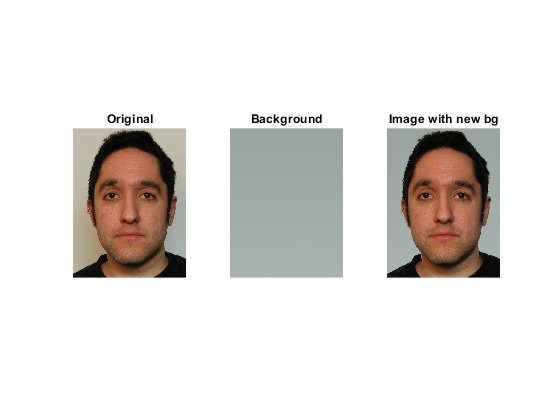

styledI_10 = styleTransfer(I,E_16,mask,bg_10, n);

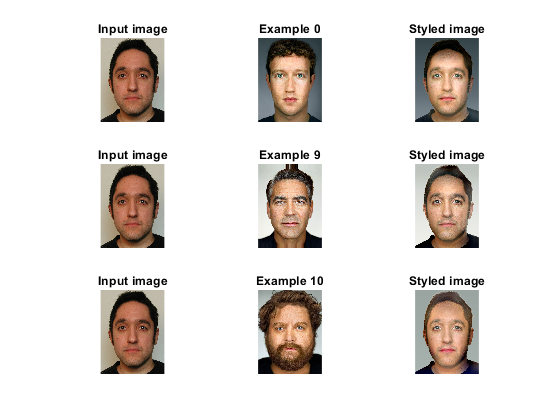


figure();
subplot(3,3,1);
imshow(I, []);
title('Input image');
subplot(3,3,2);
imshow(E_0, []);
title('Example 0')
subplot(3,3,3);
imshow(styledI_0);
title('Styled image');

subplot(3,3,4);
imshow(I, []);
title('Input image');
subplot(3,3,5);
imshow(E_9, []);
title('Example 9')
subplot(3,3,6);
imshow(styledI_9);
title('Styled image');

subplot(3,3,7);
imshow(I, []);
title('Input image');
subplot(3,3,8);
imshow(E_10, []);
title('Example 10')
subplot(3,3,9);
imshow(styledI_10);
title('Styled image');

## part h

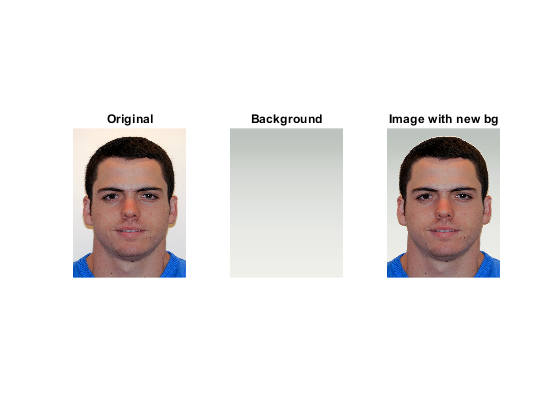

I = im2double(imread("aviv.jpg"));
mask = im2double(imread("aviv_mask.png"));
E = im2double(imread("data\Examples\imgs\9.png"));
bg = im2double(imread("data\Examples\bgs\9.jpg"));
n = 6;
styledI = styleTransfer(I,E,mask,bg, n);

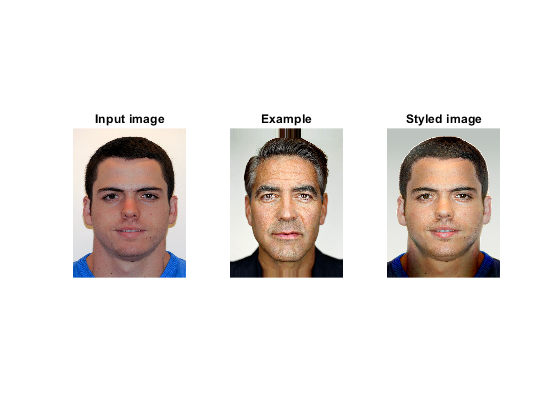


figure();
subplot(1,3,1);
imshow(I, []);
title('Input image');
subplot(1,3,2);
imshow(E, []);
title('Example')
subplot(1,3,3);
imshow(styledI);
title('Styled image');

## part i

I = im2double(imread("data\Inputs\imgs\0004_6.png"));
mask = im2double(imread("data\Inputs\masks\0004_6.png"));
E_16 = im2double(imread("data\Examples\imgs\16.png"));
bg_16 = im2double(imread("data\Examples\bgs\16.jpg"));
styledI = styleTransfer(I, E_16, mask, bg_16, n);

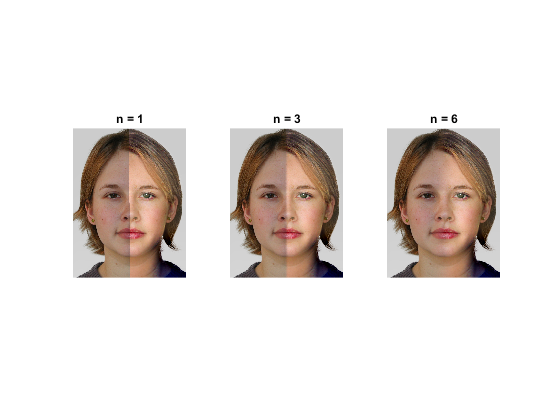

I_new_bg = changeBackground(I, mask, bg_16);
N = [1, 3, 6];
combined = {};
for i=1:length(N)
    n = N(i);
    combined = [combined; pyrBlending(I_new_bg, styledI, n)];
end
figure();
for i=1:length(N)
    n = N(i);
    subplot(1,length(N),i);
    imshow(combined{i},[]);
    title(['n = ', num2str(n)]);
end